# Setup

Before we get started, please note that this tutorial requires that you have BrainStat and all its dependencies installed. For more details see our installation guide. 

Note that we've defined a function, `pretty_plot,` at the end of this file. This function is required to make the figures look good inside a live script. If you run this code outside of a live script, please set `run_as_live_script` in the next section to false. 

% Ascertain script runs correctly both as live script and regular script.
run_as_live_script = true;
if run_as_live_script
    pretty = @pretty_plot;
else
    pretty = @(x)x;
end


## Figure 2: Statistics Module

This figure displays the statistics module. First, we'll set up and run a linear model on the MICS dataset. This model contains fixed effects for age and sex, their interaction effect, and a random effect for subject (to account for multiple measurements per subject).

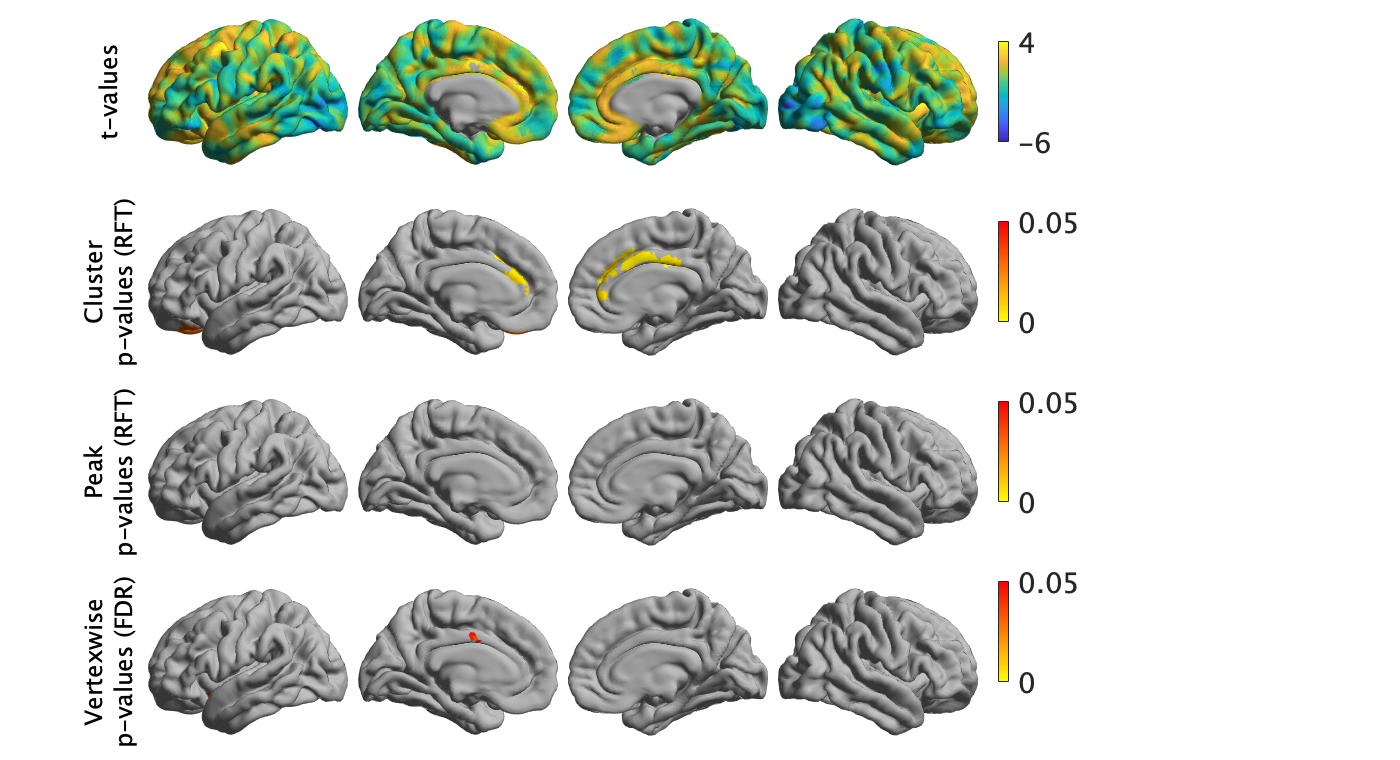

% Load data
[cortical_thickness, demographics] = fetch_mics_data();
[surf_left, surf_right] = fetch_template_surface('fsaverage5');
mask = fetch_mask('fsaverage5');

% Run the model
term_age = FixedEffect(demographics.AGE_AT_SCAN);
term_sex = FixedEffect(demographics.SEX);
term_subject = MixedEffect(demographics.SUB_ID);
model_mixed = term_age + term_sex + term_age * term_sex + term_subject;

contrast_age = -demographics.AGE_AT_SCAN;
slm = SLM( ...
    model_mixed, ...
    contrast_age, ...
    'surf', 'fsaverage5', ...
    'correction', {'fdr', 'rft'}, ...
    'cluster_threshold', 0.01, ...
    'mask', mask);
slm.fit(cortical_thickness);

% Plot the t- and p-values.
obj = tutorial_plot_slm(slm, {surf_left, surf_right}, ...
    'mask', mask, 'plot_clus', true, 'plot_fdr', true, 'plot_peak', true);
obj.colorlimits([-6, 4; 0, 0.05; 0, 0.05; 0, 0.05]);
pretty(obj);

## Figure 3: Meta-Analytic Decoding

Here we decode our t-statistic map using Neurosynth, plot it in a wordcloud, and identify top corrlations in a radar plot.

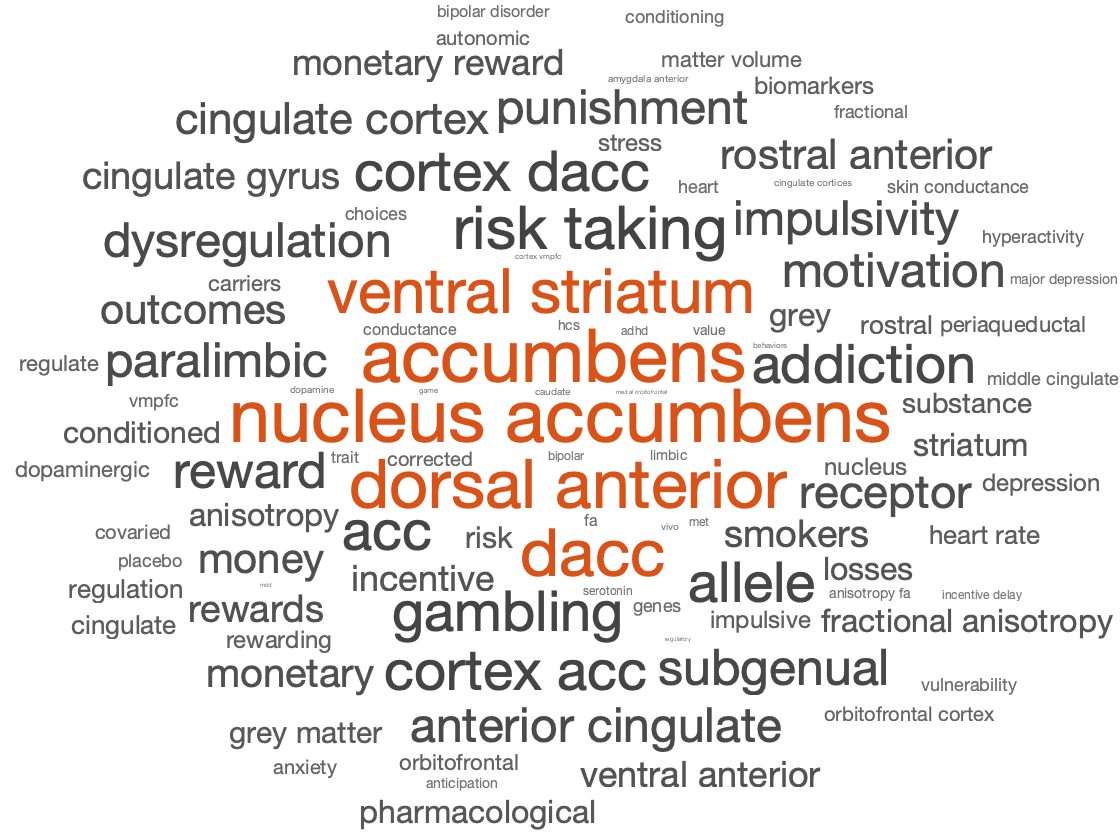

[correlation, feature] = meta_analytic_decoder(slm.t, ...
    'template', 'fsaverage5');
figure; 
wc = wordcloud(feature(correlation>0), correlation(correlation>0));

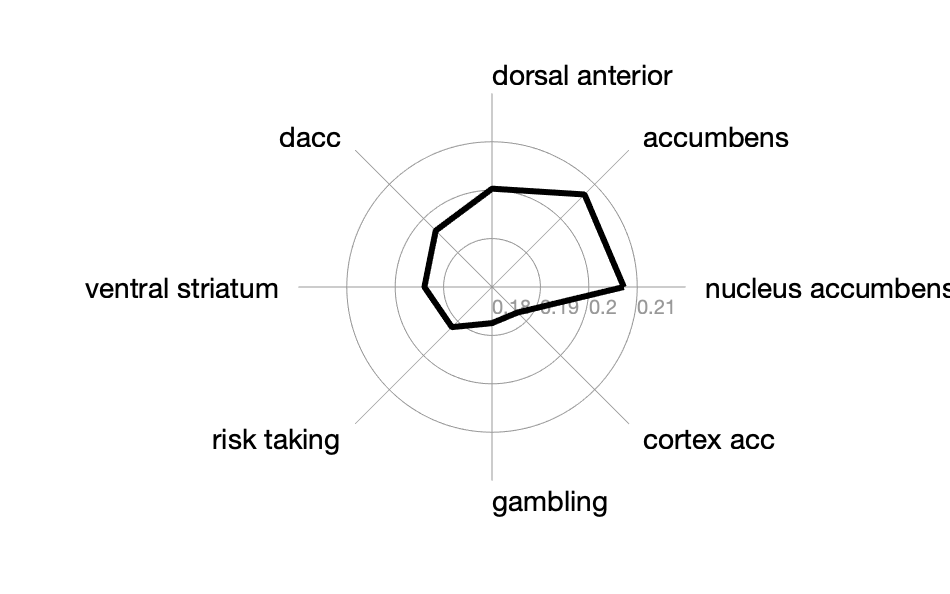


numFeat = 8;
data = correlation(1:numFeat);
label = feature(1:numFeat);
radar_plot(data, 'label', label, 'axis_range', [0.18 0.22]);

## Figure 4: Functional Hierarchy

BrainStat provides contextualization using resting-state functional gradients (Margulies et al., 2016, PNAS), a lower dimensional manifold of resting-state connectivity.

Lets have a look at the functional gradients and their correlation with the t-statistic map..

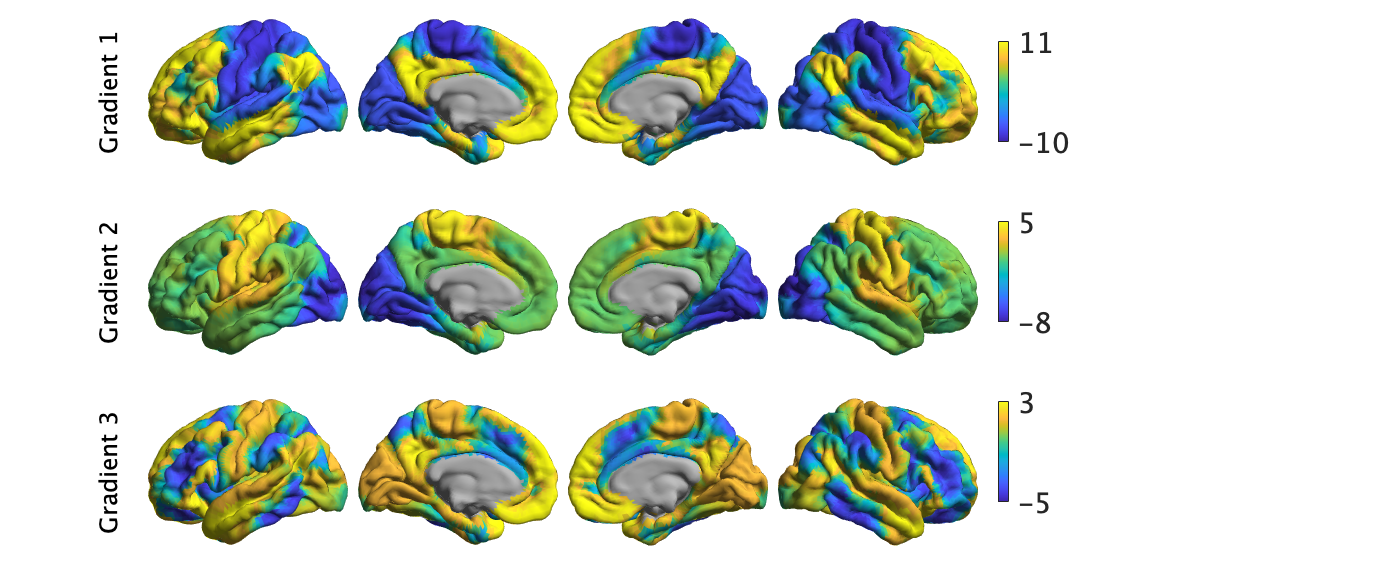

functional_gradients = fetch_gradients('fsaverage5', 'margulies2016');
gradients_plot = functional_gradients;
gradients_plot(isnan(gradients_plot)) = -inf;

% Surface plot
obj = plot_hemispheres(...
    gradients_plot(:,1:3), ...
    {surf_left, surf_right}, ...
    'LabelText', "Gradient " + (1:3));

obj.colormaps([.7 .7 .7; parula])
obj.colorlimits([-10, 11; -8, 5; -5, 3])

pretty_plot(obj)

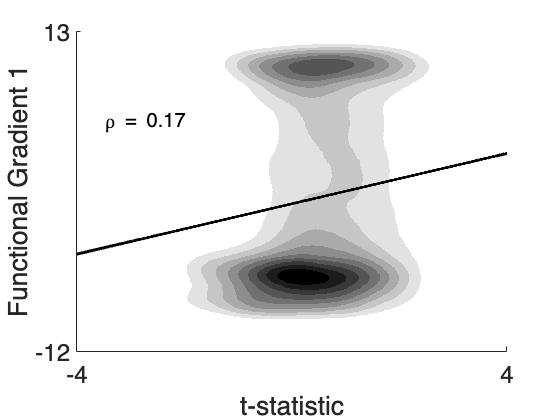

%% Kernel density plot
scatter_data = [slm.t(:), functional_gradients(:,1)];
scatter_data(any(isnan(scatter_data), 2), :) = [];

% Compute the density.
locations = {linspace(-5, 5, 1000), linspace(-14, 14, 1000)};
num_points = hist3(scatter_data, locations);
density = imgaussfilt(num_points, 30);

% Create the density plot.
h.fig = figure;
h.ax = axes;
h.img = imagesc(locations{1}, locations{2}, density');
colormap([1, 1, 1; flipud(gray(10))])
set(h.ax, ...
    'YDir', 'normal', ...
    'YTick', [-12, 13], ...
    'YLim', [-12, 13], ...
    'XTick', [-4, 4], ...
    'XLim', [-4, 4], ...
    'FontSize', 24, ...
    'Box', 'off')
xlabel('t-statistic')
ylabel('Functional Gradient 1')

% Add best fit line.
coefficients = polyfit(scatter_data(:,1), scatter_data(:,2), 1);
hold on;
h.bestfit = plot(sort(scatter_data(:,1)), ...
    polyval(coefficients, sort(scatter_data(:,1))), ...
    'k', ...
    'LineWidth', 3);

% Add correlation coefficient
rho = corr(scatter_data(:,1), scatter_data(:,2), 'type', 'spearman');
h.text = text(-3.5, 6, sprintf('\\rho = %0.2g', rho), 'FontSize', 20);

## Figure 5: Transcriptomics

We'll fetch the genetic expression data in the Allen Human Brain atlas for the schaefer 100 parcellation. Next, we plot the figures shown in the manuscript. 

[expression, gene_names] = fetch_genetic_expression('schaefer', 100);

Reading atlas from file. This may take a few minutes.


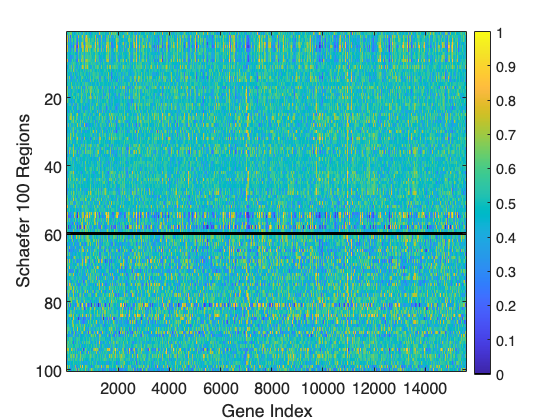

% Expression matrix
h = struct();
h.fig = figure;
h.ax = axes();
h.img = imagesc(expression);
h.cb = colorbar;
colormap([0 0 0; parula()])
set(h.ax, ...
    'XTick', 0:2000:14000, ...
    'YTick', 0:20:100, ...
    'FontSize', 16);
xlabel('Gene Index')
ylabel('Schaefer 100 Regions')

% WFDC1 Surface plot
schaefer_100 = fetch_parcellation('fsaverage5', 'schaefer', 100);

Reading from version 2
colortable with 51 entries read (originally Schaefer2018_100Parcels_7Networks)
Reading from version 2
colortable with 51 entries read (originally Schaefer2018_100Parcels_7Networks)


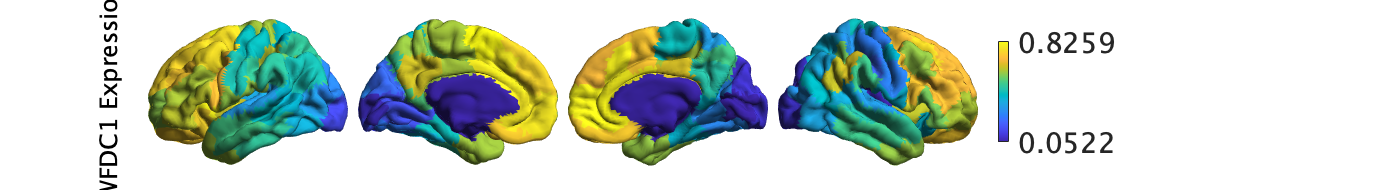

obj = plot_hemispheres(expression(:, gene_names=="WFDC1"), ...
    {surf_left, surf_right}, ...
    'parcellation', schaefer_100, ...
    'labeltext', 'WFDC1 Expression');
pretty(obj);

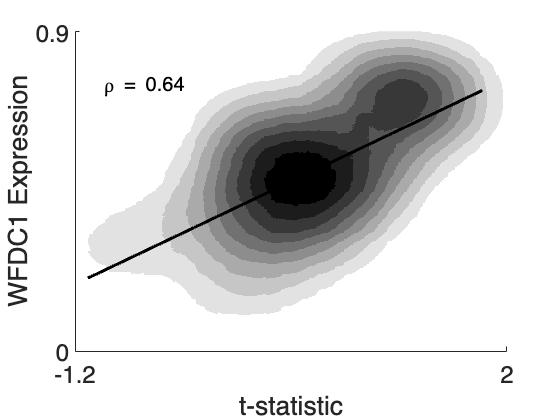

% Plot correlation between t-statistic map and WFDC1
schaefer_t_stat = full2parcel(slm.t, schaefer_100);
scatter_data_gene = [schaefer_t_stat, expression(:, gene_names=="WFDC1")];
scatter_data_gene(any(isnan(scatter_data_gene), 2), :) = [];

% Compute the density.
locations = {linspace(-1.2, 2, 1000), linspace(0, 0.9, 1000)};
num_points = hist3(scatter_data_gene, locations);
density = imgaussfilt(num_points, 100);

% Create the density plot.
h.fig = figure;
h.ax = axes;
h.img = imagesc(locations{1}, locations{2}, density');
colormap([1, 1, 1; flipud(gray(10))])
set(h.ax, ...
    'YDir', 'normal', ...
    'YTick', [0, 0.9], ...
    'YLim', [0, 0.9], ...
    'XTick', [-1.2, 2], ...
    'XLim', [-1.2, 2], ...
    'FontSize', 24, ...
    'Box', 'off')
xlabel('t-statistic')
ylabel('WFDC1 Expression')

% Add best fit line.
coefficients = polyfit(scatter_data_gene(:,1), scatter_data_gene(:,2), 1);
hold on;
h.bestfit = plot( ...
    sort(scatter_data_gene(:,1)), ...
    polyval(coefficients, sort(scatter_data_gene(:,1))), ...
    'k', ...
    'LineWidth', 3);

% Add correlation coefficient
rho = corr(scatter_data_gene(:,1), scatter_data_gene(:,2), 'type', 'spearman');
h.text = text(-1, 0.75, sprintf('\\rho = %0.2g', rho), 'FontSize', 20);

## Figure 6: Histological Decoding

For histological decoding we use microstructural profile covariance gradients, as first shown by (Paquola et al, 2019, Plos Biology), computed from the BigBrain dataset. Lets download the MPC data, compute and plot its gradients, and correlate the first gradient with our t-statistic map. Please note that due to differences in the MATLAB/Python gradient computation implementation the exact gradient values may not correspond. Furthermore, a sign reversal may occur (i.e. `python_gradient = matlab_gradient * -1`) Despite this the Python/MATLAB gradients should be highly correlated. 

% Compute MPC gradients
schaefer_400 = fetch_parcellation('fsaverage5', 'schaefer', 400);

Reading from version 2
colortable with 201 entries read (originally Schaefer2018_400Parcels_7Networks)
Reading from version 2
colortable with 201 entries read (originally Schaefer2018_400Parcels_7Networks)


histology_profiles = read_histology_profile('template', 'fsaverage5');
mpc = compute_mpc(histology_profiles, schaefer_400);

Sorting data by smallest to largest number in the label! (labelmean.m)


gradient_map = compute_histology_gradients(mpc);

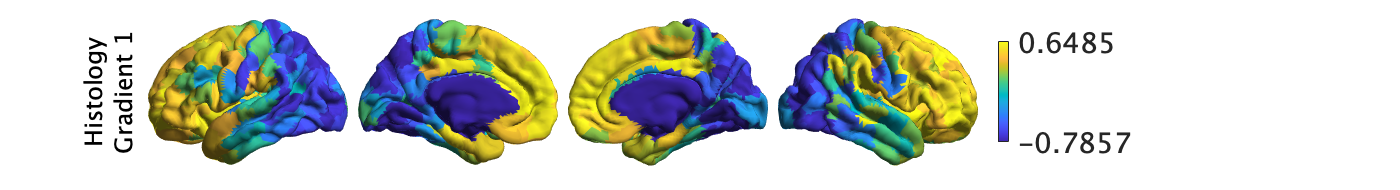

% Plot to the surface.
obj = plot_hemispheres(gradient_map.gradients{1}(:,1), ...
    {surf_left, surf_right}, ...
    'parcellation', schaefer_400, ...
    'labeltext', {{'Histology', 'Gradient 1'}});
pretty(obj);

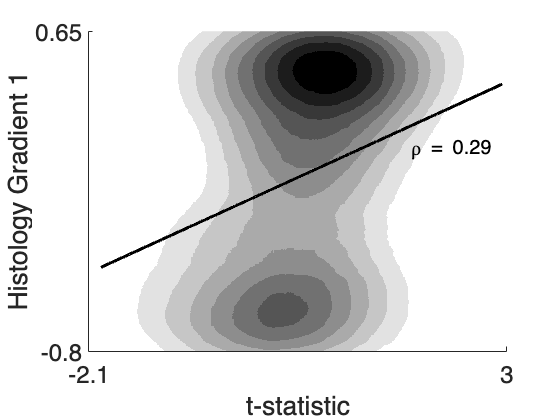

% Plot the correlation.
% Plot correlation between t-statistic map and WFDC1
schaefer_400_t_stat = full2parcel(slm.t, schaefer_400);
scatter_data_hist = [schaefer_400_t_stat, gradient_map.gradients{1}(:,1)];
scatter_data_hist(any(isnan(scatter_data_hist), 2), :) = [];

% Compute the density.
locations = {linspace(-2.1, 3, 1000), linspace(-0.8, 0.65, 1000)};
num_points = hist3(scatter_data_hist, locations);
density = imgaussfilt(num_points, 100);

% Create the density plot.
h.fig = figure;
h.ax = axes;
h.img = imagesc(locations{1}, locations{2}, density');
colormap([1, 1, 1; flipud(gray(10))])
set(h.ax, ...
    'YDir', 'normal', ...
    'YTick', [-0.8, 0.65], ...
    'YLim', [-0.8, 0.65], ...
    'XTick', [-2.1, 3], ...
    'XLim', [-2.1, 3], ...
    'FontSize', 24, ...
    'Box', 'off')
xlabel('t-statistic')
ylabel('Histology Gradient 1')

% Add best fit line.
coefficients = polyfit(scatter_data_hist(:,1), scatter_data_hist(:,2), 1);
hold on;
h.bestfit = plot( ...
    sort(scatter_data_hist(:,1)), ...
    polyval(coefficients, sort(scatter_data_hist(:,1))), ...
    'k', ...
    'LineWidth', 3);

% Add correlation coefficient
rho = corr(scatter_data_hist(:,1), scatter_data_hist(:,2), 'type', 'spearman');
h.text = text(1.8, 0.12, sprintf('\\rho = %0.2g', rho), 'FontSize', 20);

function pretty_plot(obj)
% Makes the BrainSpace plots prettier inside live scripts.
obj.handles.figure.Units = 'pixels';
set(obj.handles.axes, 'Units', 'pixels')
set(obj.handles.colorbar, 'Units', 'pixels');
obj.handles.figure.Position = [1, 1, 700, size(obj.data, 2) * 95];
set(obj.handles.text, 'FontSize', 12);

for jj = 1:size(obj.data, 2) % variates
    obj.handles.colorbar(jj).Position = [...
        500, ...
        30 + (size(obj.data, 2) * 95) - 10 - jj*90, ...
        5, ...
        50];
    for ii = 1:4 % views
        obj.handles.axes(jj, ii).Position = [...
            75 + (ii-1)*105, ...
            (size(obj.data, 2) * 95) - jj*95, ...
            100, ...
            100];
    end
end
end